# Image Processing

TODO: describe the process after enhanced image is taken.

globals();
global formatted_dataset_path preprocessed_images; % data
global number_defect_classes; % data info
global column_image_id column_encoded_pixels; % columns

colormap('gray'); % because imshow is not convenient in this case so imagesc is used instead

% Load dataset
opts = detectImportOptions(formatted_dataset_path);
dataset = readtable(formatted_dataset_path , opts);

% Load sample image
image_row = dataset(round(rand(1) * size(dataset,1)),:);
image_id = image_row{1,column_image_id}{1};
image = imread(sprintf("%s%s",preprocessed_images,image_id));

To decode rle into a b/w map .....

map = zeros(size(image));
% Decode rle encoded pixels 
for class_id = 1 : number_defect_classes
    encoded_pixels = image_row{1,sprintf("%s%d",column_encoded_pixels,class_id)}{1};
    [~,pixels] = rle_decoding(encoded_pixels,size(image));
    map = map | pixels;
end

Compare image and map ....

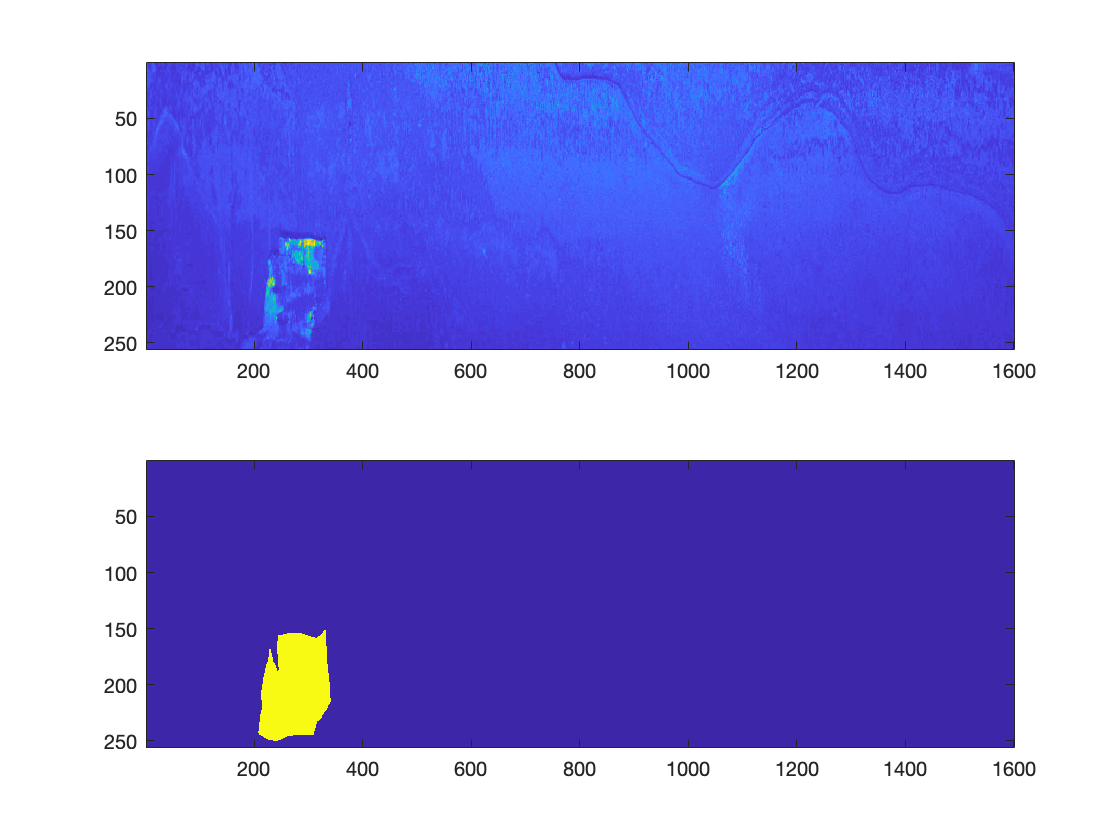

figure;
subplot(2,1,1);
title("Image");
imagesc(image);
subplot(2,1,2);
title("Map");
imagesc(map * 255);

Segmentation & bounding box ...

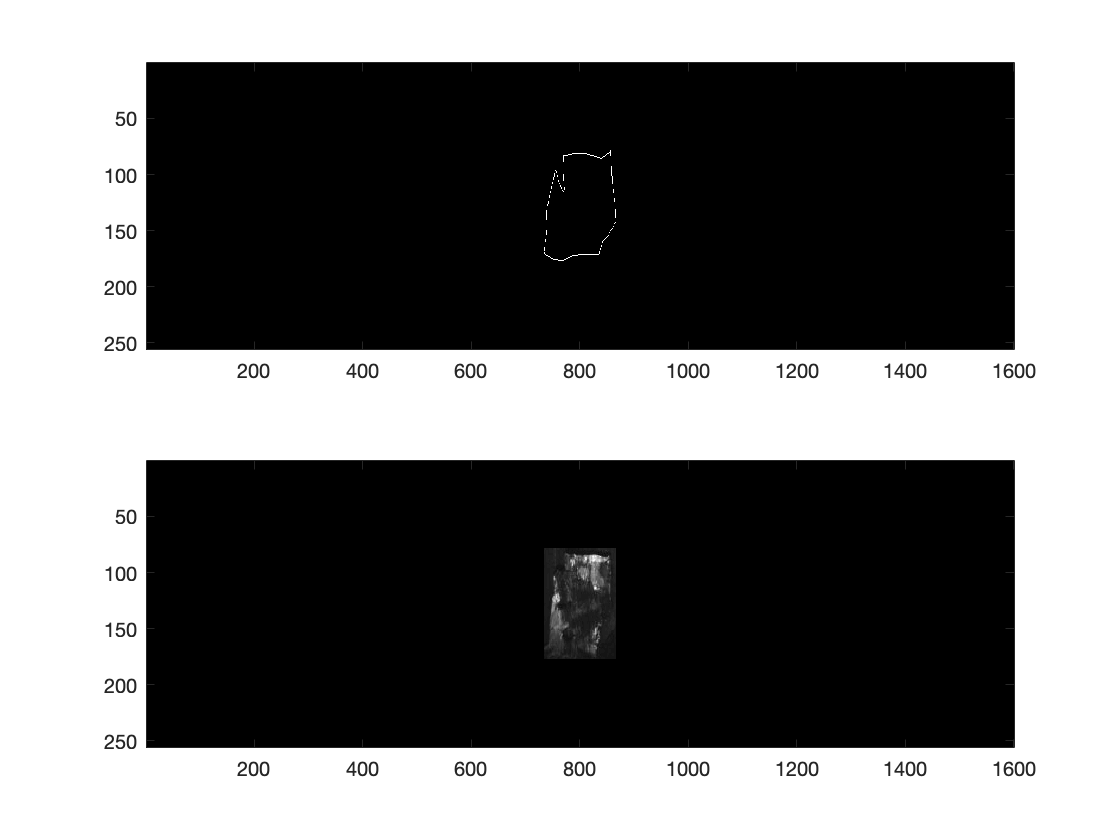

if find(map ~= 0)
    [number_of_regions encoded_shape_features bounding_boxes] = segmentate_image(map);
    % Iterate over regions
    for region_id = 1 : number_of_regions
        [shape_feature, local_feature] = bounds2localfeature(...
            encoded_shape_features(region_id), ...
            bounding_boxes(:,:,region_id), image);
        % display shape feature
        figure;
        subplot(2,1,1);
        title(sprintf("Shape feature of region %d",region_id));
        imagesc(shape_feature)
        % display local feature
        subplot(2,1,2);
        title(sprintf("Local feature of region %d",region_id));
        imagesc(local_feature);
        colormap('gray');
    end
else
    "Flawless surface sampled."
end